# Assignment 6 in ModSim

***By Alexander Rambech***

#### Task 1

**a)**

It's a DAE because the variable $z$ is not part of the equation with as a time derivative. The equation is therefore a DAE.

**b)**

In order to find the order of the DAE we differentiate the semi-expicit DAE $g = 0 = \frac{1}{2}\left(x_1^2 + x_2^2 -1 \right)$. 

We see that by differentiating twice we get:

- 
$$g'' = \dot{x}_1 (x_1 + x_2 +z ) + \dot{x}_2(z + u) + x_1 (\dot{x}_1 + \dot{x}_2 + \dot{z}) + x_2(\dot{z} + \dot{u})$$


This yields the differential equation:

- 
$$\dot{z} = \frac{-\dot x (z+u) - x_1 \dot x_2 -x_1 \dot x_1 - \dot x (x_1 + x_2 + z) - x_2\dot u}{x_1 + x_2}$$


This holds because we know that $x_1 + x_2 = 0$.

**c)**

Since we have DAE of 2nd order, we only have to differentiate once to reduce the index, this yields:

- 
$$g' = x^2_1 + x_1x_2+x_2u+(x_1+x_2)z$$


#### Task 2

**a)**

We can clearly see that given that if $\epsilon = 0$, the equation is a DAE, because $z$ has no derivative in any of the expressions. Conversely, it is an ODE if $z > 0$.

**b)**

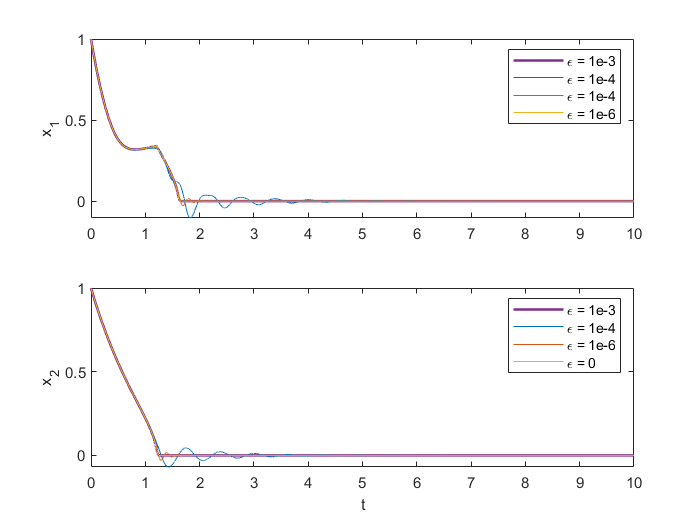

% Initializing model
clear
syms x1 x2 z1 z2 u epsilon alpha real;
M = - [1 1;
       0 1];
x = [x1;
     x2];
z = [z1;
     z2];
dx = M*x-z;
A = [x1^2 x2; 
     0 x2^2]+  alpha*eye(2);
dz = simplify(1/10*x-A*z)/epsilon;
z_dae = simplify((1/10)*x-A*z);


% Initializin paramters
epsilon =1e-3;
alpha = 1e-3;
init = [1 1 0 0];
tf = 10;
tspan = [0 tf];
param = [epsilon,alpha];
setings = odeset('RelTol',1e-12,'AbsTol',1e-16);

dae_sol = solve(z_dae==0,z);
dae_sol = simplify([dae_sol.z1;dae_sol.z2]);


[t_0,x_0] = ode15s(@(t,x)ODEfunc(t,x,param),tspan,init,setings);
epsilon =1e-4;
param = [epsilon,alpha];
[t_1,x_1] = ode15s(@(t,x)ODEfunc(t,x,param),tspan,init,setings);

epsilon =1e-6;
param = [epsilon,alpha];
[t_2,x_2] = ode15s(@(t,x)ODEfunc(t,x,param),tspan,init,setings);
epsilon =0;
param = [epsilon,alpha];
[t_3,x_3] = ode15s(@(t,x)DAEfunc(t,x,param),tspan,[1 1],setings);
figure()
subplot(2,1,1)
plot(t_0,x_0(:,1))
hold on
plot(t_1,x_1(:,1))
plot(t_2,x_2(:,1))
d = plot(t_3,x_3(:,1),'linewidth',1.5);

uistack(d,'bottom')
hold off
legend('\epsilon = 1e-3','\epsilon = 1e-4','\epsilon = 1e-4','\epsilon = 1e-6')
ylabel('x_1')
subplot(2,1,2)
plot(t_0,x_0(:,2))
hold on

plot(t_1,x_1(:,2))
plot(t_2,x_2(:,2))
d = plot(t_3,x_3(:,2),'linewidth',1.5);

uistack(d,'bottom')
hold off
legend('\epsilon = 1e-3','\epsilon = 1e-4','\epsilon = 1e-6','\epsilon = 0')
ylabel('x_2')
xlabel('t')

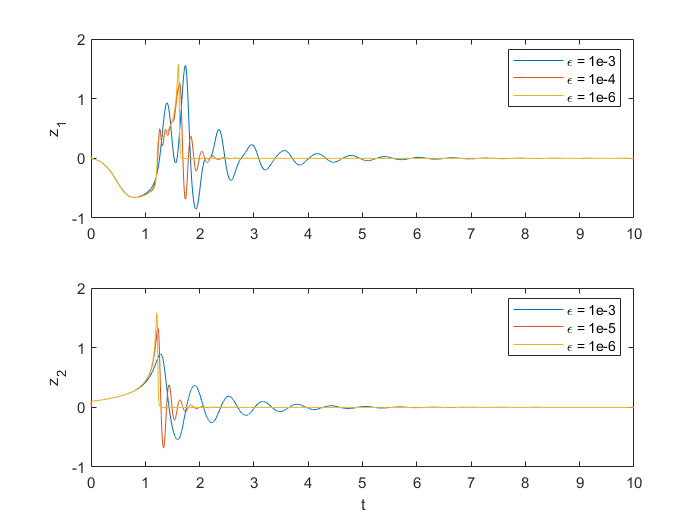

figure()
subplot(2,1,1)
plot(t_0,x_0(:,3))
hold on

plot(t_1,x_1(:,3))
plot(t_2,x_2(:,3))
hold off
legend('\epsilon = 1e-3','\epsilon = 1e-4','\epsilon = 1e-6')
ylabel('z_1')
subplot(2,1,2)
plot(t_0,x_0(:,4))
hold on

plot(t_1,x_1(:,4))
plot(t_2,x_2(:,4))
hold off
legend('\epsilon = 1e-3','\epsilon = 1e-5','\epsilon = 1e-6')
ylabel('z_2')
xlabel('t')

**c)**

% New alpha
alpha = 0;

param = [epsilon,alpha];
[t_0,x_0] = ode15s(@(t,x)ODEfunc(t,x,param),tspan,init,setings);

epsilon =1e-4;
param = [epsilon,alpha];
[t_1,x_1] = ode15s(@(t,x)ODEfunc(t,x,param),tspan,init,setings);

epsilon =1e-6;
param = [epsilon,alpha];
[t_2,x_2] = ode15s(@(t,x)ODEfunc(t,x,param),tspan,init,setings);
epsilon =0;
param = [epsilon,alpha];
[t_3,x_3] = ode15s(@(t,x)DAEfunc(t,x,param),tspan,[1 1],setings);

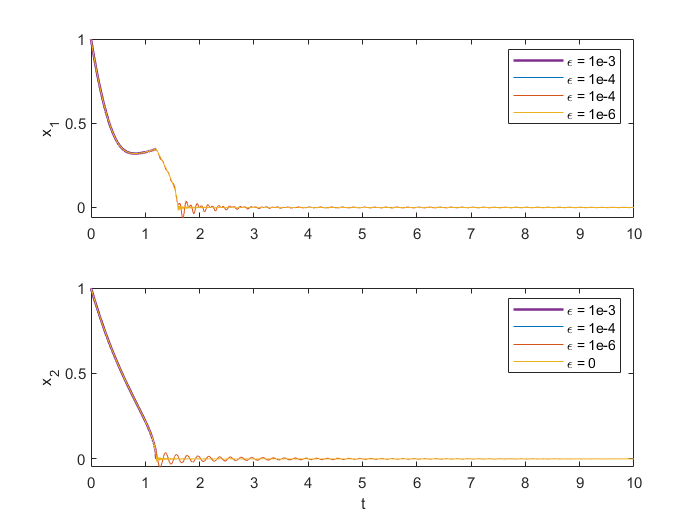

figure()
subplot(2,1,1)
plot(t_0,x_0(:,1))
hold on
plot(t_1,x_1(:,1))
plot(t_2,x_2(:,1))
d = plot(t_3,x_3(:,1),'linewidth',1.5);

uistack(d,'bottom')
hold off
legend('\epsilon = 1e-3','\epsilon = 1e-4','\epsilon = 1e-4','\epsilon = 1e-6')
ylabel('x_1')
subplot(2,1,2)
plot(t_0,x_0(:,2))
hold on

plot(t_1,x_1(:,2))
plot(t_2,x_2(:,2))
d = plot(t_3,x_3(:,2),'linewidth',1.5);

uistack(d,'bottom')
hold off
legend('\epsilon = 1e-3','\epsilon = 1e-4','\epsilon = 1e-6','\epsilon = 0')
ylabel('x_2')
xlabel('t')

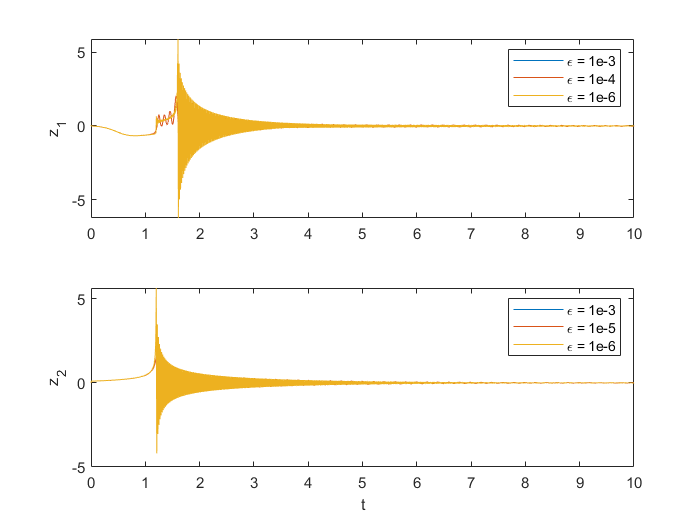

figure()
subplot(2,1,1)
plot(t_0,x_0(:,3))
hold on

plot(t_1,x_1(:,3))
plot(t_2,x_2(:,3))
hold off
legend('\epsilon = 1e-3','\epsilon = 1e-4','\epsilon = 1e-6')
ylabel('z_1')
subplot(2,1,2)
plot(t_0,x_0(:,4))
hold on

plot(t_1,x_1(:,4))
plot(t_2,x_2(:,4))
hold off
legend('\epsilon = 1e-3','\epsilon = 1e-5','\epsilon = 1e-6')
ylabel('z_2')
xlabel('t')

**b)**

#### Task 3

**a)**

We clearly see by the equations that $u$ has no derivatives, given this is a variable of it's own right we can say that the this is a DAE. Using $u$ can cause som confusion tho. To avoid this we should use an other name.

**b)**

The same goes for this equation. It is not an ODE because $u$ has no derivative here either. However, to check if it is a DAE we check if the jacobian matrix of the system is of full rank:

clear
syms x1 x2 dx1 dx2 u real;
x = [x1;
     x2];
dx = [dx1;
      dx2];
f = [u+x.'*dx;
     u*x.'*dx]

$$f = \left(\begin{array}{c} u+{\mathrm{dx}}_{1}\,x_{1}+{\mathrm{dx}}_{2}\,x_{2}\\ {\mathrm{dx}}_{1}\,u\,x_{1}+{\mathrm{dx}}_{2}\,u\,x_{2} \end{array}\right)$$

df = jacobian(f, x)

$$df = \left(\begin{array}{cc} {\mathrm{dx}}_{1} & {\mathrm{dx}}_{2}\\ {\mathrm{dx}}_{1}\,u & {\mathrm{dx}}_{2}\,u \end{array}\right)$$

det(df)

$$ans = 0$$

We see the determinant of the jacobian is $0$ and system is there for not full rank and not a DAE

#### Task 4

**a) **

No, trigonometric functions cannot be semi-explicit.

function state_dot = ODEfunc(t,states,param)
    x1 = states(1);
    x2 = states(2);
    z1 = states(3);
    z2 = states(4);
    M = - [1 1;0 1];
    x= [x1;x2];
    z= [z1;z2];
    A = [x1^2 x2; 0 x2^2]+param(2)*eye(2);
    dx = M*x-z;
    dz = (1/10*x-A*z)/param(1);
    state_dot = [dx;dz];
end

function state_dot = DAEfunc(t,states,param)
    x1 = states(1);
    x2 = states(2);
    x= [x1;
        x2];
    alpha = param(2);
    z = [(alpha*x1+x1*x2^2-x2^2)/(10*(x1^2+alpha)*(x2^2+alpha));
        x2/(10*(x2^2+alpha))];
    M = - [1 1;0 1];
    dx = M*x-z;
    state_dot = [dx];
end